# **Optimal Consumption in Two Periods**

[**Back to Fan's Math for Economist Table of Content**](https://fanwangecon.github.io/Math4Econ/)

We previously solved for the unconstrained household's savings and borrowing problem:  [unconstrained problem](https://fanwangecon.github.io/Math4Econ/derivative_application/K_save_households.html). And also the [constrained optimization](https://fanwangecon.github.io/Math4Econ/optimization_application/household_borrow_constrained.html) problem with asset choice.

## Effects of Changing R

- **Utility**: $U(c_{1}, c_{2}) = \log(c_{1}) + 0.95 \cdot \log(c_{2})$

- **Budget Today**: $c_{1} + b \le Z_1$

- **Budget Tomorrow**: $c_{2} \le b\cdot (1+ r ) + Z_2$

We have solved this problem as an unconstrained maximization problem by eliminating the consumption terms. If we keep the consumption terms but eliminatethe $b$ term, then the problem is a constrained maximization problem with an income constraint. The income constraints are always going to bind because households will not waste income given log utility which is always increasing in consumption:

- **constraint**: $c_{2} \le (z_1 - c_1)(1+r) + Z_2$, $c_1 \ge 0$, $c_2 > 0$

We can combine the two periods' income constraints together because there is no uncertainty. We can not do this for the problem with [uncertainty](https://fanwangecon.github.io/Math4Econ/nonlinear/RiskyAsset.html). 

## Solution to the Constrained Problem

We can state the constrained maximization problem as this (we have already found the solution to this problem before solving it as an [unconstrained problem](https://fanwangecon.github.io/Math4Econ/derivative_application/K_save_households.html), the solution will be the same). Note that the budget constraint when written this way shows that a resource increase in either $Z_1$ or $Z_2$ can be spent on the first or second period because we are allowed to freely borrow and save. And that the cost of first period consumption is priced at interest rate $1+r$. 

- 
$$\max_{c_1, c_2} \log(c_{1}) + 0.95 \cdot \log(c_{2})$$


- $c_1 \ge 0$, $c_2 > 0$, and $c_2 + (1+r) c_1 \le Z_1 (1+r) + Z_2$

You can solve this problem as we did in class with [lagrange multipliers](https://fanwangecon.github.io/Math4Econ/optimization_application/household_borrow_constrained.html).

## Matlab Solution to the Constrained Problem

Following what we did in the [unconstrained problem with labor and asset choice](https://fanwangecon.github.io/Math4Econ/optimization_application/household_asset_labor_constrained.html), where we also had a borrowing constraint, we can use fmincon again. The constraints are:

- 
$$c_2 + (1+r) c_1 \le Z_1 (1+r) + Z_2$$


- 
$$-c_1 \le 0$$


- 
$$-c_2 \le 0$$


To useThis is a linear system, the equations above are equal to:

- 
$$(1) c_2 + (1+r) c_1 \le Z_1(1+r) + Z_2$$


- 
$$(0) c_2 + (-1) c_2 \le 0$$


- 
$$(-1) c_2 + (0) c_2 \le 0$$


Which mean that we have a $A$ matrix and $q$ vector:

- 
$$\left[ {\begin{array}{cc} 1 & 1+r \\  0 & -1 \\  -1 & 0 \end{array} } \right] \cdot \left[ {\begin{array}{c} c_2 \\ c_1 \end{array} } \right] \le \left[ {\begin{array}{c} Z_1(1+r) + Z_2 \\ 0 \\ 0 \end{array} } \right]$$


Now we can set up the inputs for fmincon

clear all
% Parameters
beta = 0.95;
z1 = 1;
z2 = 2;
r = 0.05;

% Write down the objective function, we will define it as a function handle, negative utility for minimization
U_neg = @(x) -1*(log(x(1)) + beta*log(x(2)));
% Constraint derived above
A = [1,1+r;0,-1;-1,0];
q = [(z1*(1+r) + z2);0;0];

Now call fminunc to solve

c_init = [0.5,0.5]; % starting value to search for optimal choice
% U_neg_num = matlabFunction(subs(U_neg, {beta, z1, z2, r}, {beta_num, z1_num, z2_num, r_num}));
[c_opti,U_neg_at_c_opti] = fmincon(U_neg, c_init, A, q);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

c1_opti = c_opti(1);
c2_opti = c_opti(2);
U_at_c_opti = -1*U_neg_at_c_opti;
disp(table(c1_opti, c2_opti, U_at_c_opti));

    c1_opti    c2_opti    U_at_c_opti
    _______    _______    ___________

    1.5641     1.4151       0.77718  



Note that consumption in the two periods are similar. Households generally want to smooth consumption over time given their differential endowments in each period. 

## Graphical Representation

We can represent the budget constraint and utility function (objective function) graphically. When we plug the optimal choices back into the utility function, we have the ***indirect utility***.

- **Indirect Utility function**: $V(c^*_1(r,Z_1,Z_2), c^*_2(r,Z_1,Z_2)) = V(r,Z_1,Z_2)$

Note that the indirect utility is a function of the price $r$ that households face, and the resources the have available--their income--$Z_1,Z_2$. We can also write:

- 
$$V(r,Z_1,Z_2) = \max_{c_1, c_2} U(c_1, c_2; r, Z_1, Z_2)$$


At a particular $r,Z_1,Z_2$, we have a specific numerical value for $V^*$. We have different bundles of $c_1, c_2$ that can all achieve this particular utility level $V^*$. We can draw these and see visually where the optimal choices are. So we have two equations that we can draw:

- Budget:$(1) c_2  \le Z_1(1+r) + Z_2 - (1+r) c_1$

- Indifference at $V^*$: $V^* = \log(c_1) + \beta \log(c_2)$, which is: $c_2 = \exp \left( \frac{V^* - \log(c_1)}{\beta}\right)$

Think of $c_1$ as the x-axis variable, and $c_2$ as the y-axis variable, we can plot them together

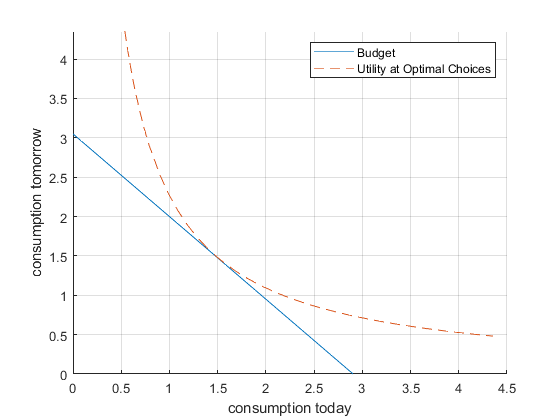

% Numbers defined before, and U_at_c_opti found before
syms c1
% The Budget Line
f_budget = z1*(1+r) + z2 - (1+r)*c1;
% Indifference at V*
f_indiff = exp((U_at_c_opti-log(c1))/(beta));
% Graph
figure();
hold on;
fplot(f_budget, [0, (z1 + z2/(1+r))*1.5]);
fplot(f_indiff, [0, (z1 + z2/(1+r))*1.5], '--');
ylim([0, (z1 + z2/(1+r))*1.5])
xlabel('consumption today');
ylabel('consumption tomorrow');
legend({'Budget', 'Utility at Optimal Choices'})
grid on;